## Inputs

Please manually change the following numbers. The following diagram should be used for fin geometry.

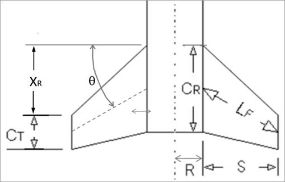

clear
clc

% % Yield Stress of Material (at max compressive force location) (psi)
% % You will have to run the calculator once and then update this value
% Fy = 35000; THIS VALUE IS NOT USED

% High thrust condition
    % Burnout altitude
    burn_alt = 5709; % ft
    % Air Density at burnout alt (lbm/ft^3) (5709 ft)
    rho = 0.065;        %%%%% DOUBLE CHECK BURNOUT ALT
    % Burnout Velocity (ft/s),  (Ma = 0.8)
    burn_v = 969;       %%%%% DOUBLE CHECK VELOCITY
    % Mach Number
    Ma = 0.8;             %%%%% DOUBLE CHECK
    % Maximum Acceleration (ft/s^2)
    a_max = 116;         %%%%% DOUBLE CHECK

% Vehicle Wet Mass (lb)
m_wet = 173;        %%%%% DOUBLE CHECK
% Coefficient of Drag
cd = 1;             %%%%% RECALCULATE?
% Vehicle Outer Diameter (in)
d = 8;
% Vehicle Outer Radius (in)
r = d/2;
% Airframe Wall Thickness (in)
t_skin = 0.03;      %%%%% NOT NEEDED?
% Angle of Attack (rad) (usually 5-10 deg (0.08-0.16 rad) for worst case)
aoa = 0.08;
% Fin Geometry (in) %%%%% DOUBLE CHECK CURRENT FINS
N = 3; % number of fins
R = r; % vehicle outer radius
S = 8.25; % fin span
Xr = 5.25; % distance between leading edge of root and leading edge of tip
Ct = 15.75; % tip length
Cr = 15; % root length
% Cn_alpha for nosecone (find in OpenRocket) (rad^-1)
Cn_alpha_nose = 2;  % From Nakka: Assume to be 2
% Distance from tip of nosecone to start of fins (in)
xb = 173;
% Nosecone length (in)
L_nose = 40;  %%%%% CHANGE LENGTH, CHANGED!
% Cg location from tip of nosecone (in)
Xcg = 116;
% Boat-Tail Geometry (find in Openrocket)
L_bt = 0.5; % (in)
dr_bt = 4.5; % (in)
Xp = 171; % length from nosecone to start of boat tail

### Calculations and Outputs

The following image is used for reference for lateral acting inertial loads.

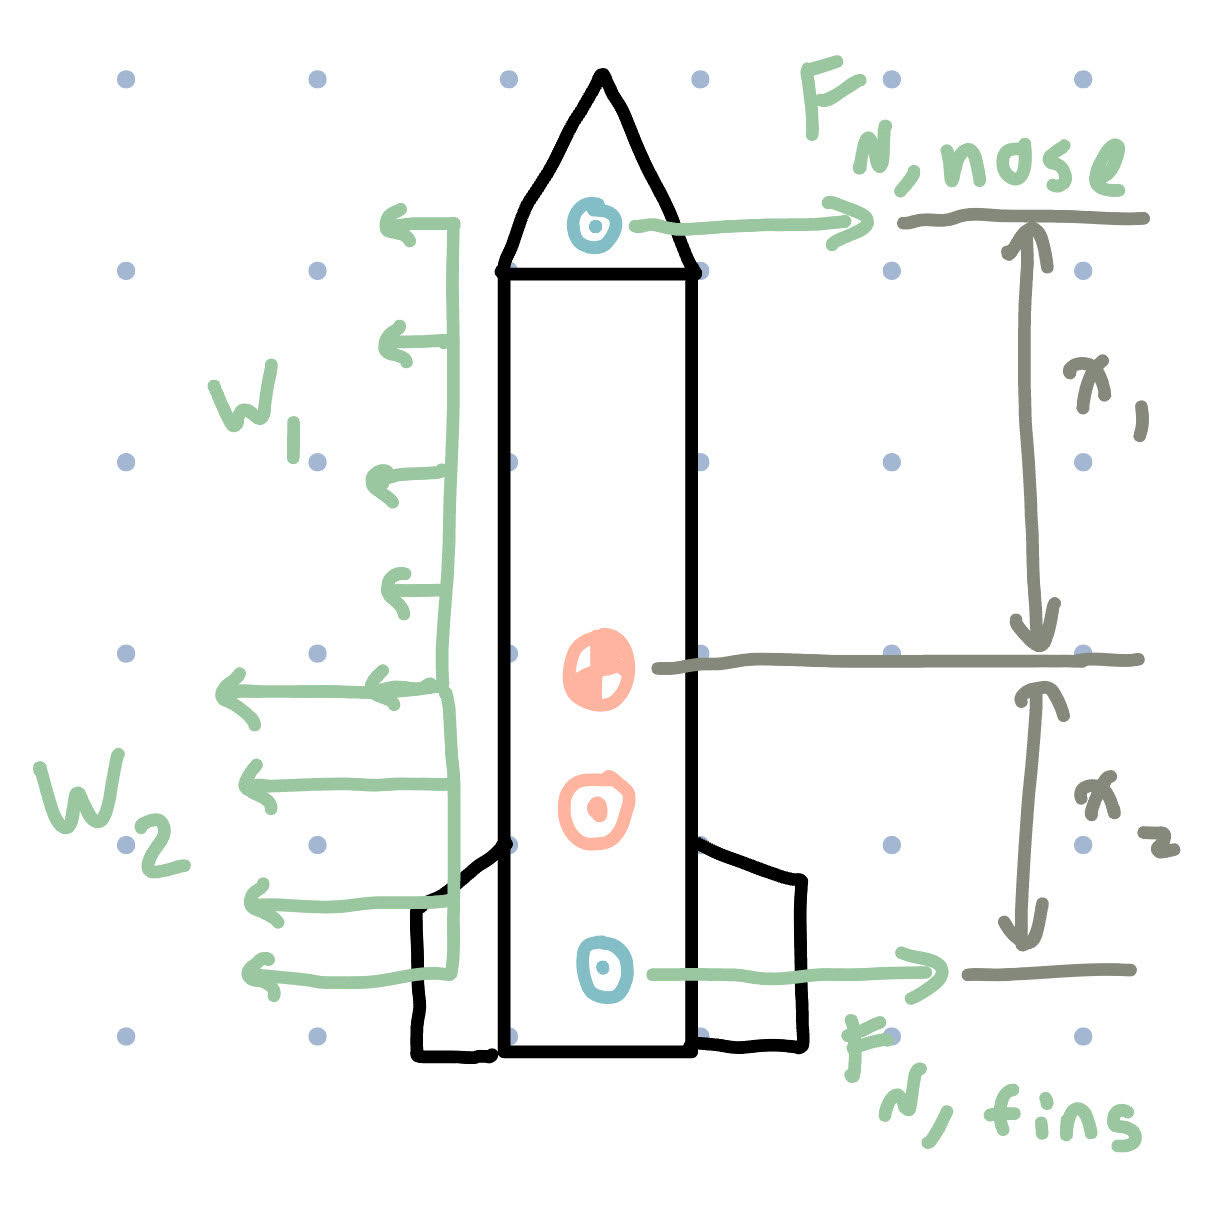

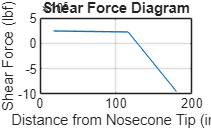

% Max drag calc
front_area = (1/4)*pi*d^2;  % in^2
F_d = 0.5*rho*burn_v^2*cd*front_area;

% Max dynamic pressure
q = 0.5*rho*burn_v^2;       % lbf/in^2

% Fin geometry
theta = atand((1/S)*(Xr+0.5*(Ct-Cr)));
Lf = S/(cosd(theta));

% Normal forces
% Cn_alpha_fins = (1+(R/(S+R))) * ((4*N*(S/d)^2) / (1+sqrt(1+((2*Lf)/(Cr+Ct))^2)))
Cn_alpha_fins = 7.779; % Obtain from Openrocket
Fn_fins = q*front_area*aoa*Cn_alpha_fins;

Fn_nose = q*front_area*aoa*Cn_alpha_nose;

% Boat Tail Lift
A_boat = -1.3*(L_bt/d)^2 + 6.35*(L_bt/d)- 7.85;

C_nalpha0boat = (1-(dr_bt/d)^2)*(-0.6-1.4*exp(A_boat*(Ma-1)^0.8));

Cn_boat = C_nalpha0boat*sin(aoa)*cos(aoa)*(1-(sin(aoa)^0.6));

Fn_boat = q*front_area*aoa*Cn_boat;

% Center of pressure locations
    % COP of nose cone 
    Xn = 0.446*L_nose; % equation for ogive shape nose cone, from Barrowman
    % COP of fins, in componentsb
    Xf1 = xb;
    Xf2 = (Xr*(Cr+2*Ct))/(3*(Cr+Ct));
    Xf3 = (1/6)*((Cr+Ct)-((Cr*Ct)/(Cr+Ct)));
    % COP of fins
    Xf = Xf1+Xf2+Xf3;
    % COP of boat tail
    Xbt = Xp + (L_bt/3)*(1+(1-(d/dr_bt))/(1-(d/dr_bt)^2));

% Lateral acting inertia loads (lbf)
x1 = Xcg-Xn;
x2 = Xf-Xcg;
W2 = (Fn_fins*(2*x2+x1)-Fn_nose*x1)/(x2^2+x1*x2); % for x1<=x<=x2
W1 = (Fn_nose+Fn_fins-W2*x2)/x1; % for 0<=x<=x1

% Shear Loading and Moment Calcs
L_tot = x1+x2;
n = 90; % CHANGE THIS VALUE TO HAVE MORE PLOT POINTS, used to be 100; IT SHOULD MATCH LENGTH OF INERTIA VECTORS?
x = linspace(0,L_tot,n);
i = 1;
V = zeros(1,n); % matrix for shear force
M = zeros(1,n); % matrix for bending moment

while x(i) <= x1
    V(i) = Fn_nose-W1*x(i);
    M(i) = Fn_nose*x(i)-0.5*W1*(x(i))^2;
    i = i+1;
end

V1 = Fn_nose-W1*x1;

while x(i) < L_tot
    V(i) = V1-W2*(x(i)-x1);
    M(i) = V1*x(i)-0.5*W2*(x(i))^2+W2*x1*x(i)+0.5*W2*(L_tot)^2-L_tot*(V1+W2*x1);
    i = i+1;
end

V(i) = V1-W2*(L_tot-x1); %these are here to get last V&M values because loop was being stupid
M(i) = V1*L_tot-0.5*W2*(L_tot)^2+W2*x1*L_tot+0.5*W2*(L_tot)^2-L_tot*(V1+W2*x1);

% The previous calcs were done using a relative coordinate system
% The following plots shear and moment w.r.t. true coordinates
% Nosecone tip is x=0 in
x_true = x+Xn;

plot(x_true,V)
hold on
xlabel('Distance from Nosecone Tip (in)')
ylabel('Shear Force (lbf)')
title('Shear Force Diagram')
grid on
hold off

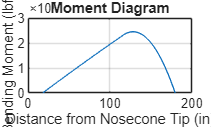


plot(x_true,M)
hold on
xlabel('Distance from Nosecone Tip (in)')
ylabel('Bending Moment (lbf*in)')
title('Moment Diagram')
grid on
hold off


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


#### Bending Stiffness

% Importing excel data
filename =  "C:\Users\Home\Desktop\APRL\DimensionSets.xlsx"; % (use "copy as path")
T = readtable(filename);


% This command will add whatever labels you have in the first row on the table but it's not needed for what we're doing, just for reference
b = T{:,2}';  
h = T{:,3}';
t = T{:,4}';
% Data imports as a table (not matrix), this makes it a matrix then transpose to get row instead of column

% Area moment of inertia about x-axis

    
% Vector: stringers a & c
Ixx_ac = T{:,7}';
% Vector: stringers b & d
Ixx_bd = T{:,9}';
% Skin    
Ixx_sk = T{:,10}'; % in^4

% Material properties
E_st = 10000*10^3;  % lbf/in^2  -  6061 T6 Aluminum
E_sk = 10200*10^3;  % lbf/in^2  -  5052 Aluminum
Y_st = 40*10^3;     % lbf/in^2  -  6061 T6 Aluminum
Y_sk = 23*10^3;     % lbf/in^2  -  5052 Aluminum

% Bending stiffness
% H33 = E_st*(2*Ixx_ac + 2*Ixx_bd) + E_sk*(Ixx_sk)    % lbf*in^2

% Loop through all dimension sets, d = number of dimensions sets
d = length(Ixx_ac);
H33 = zeros(1,d);

for i = 1:d
    H33(i) = E_st.*(2.*Ixx_ac(i) + 2.*Ixx_bd(i)) + E_sk.*(Ixx_sk(i));
end

#### Axial Stresses

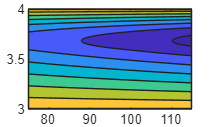

% x2 (y) locations (heights) above x1 axis
% Stringer CG/COM height
% height_st_ac = 3.705;   % in
% height_st_bd = 0;       % in
% % Skin center height
% height_sk = d/2 - t_skin/2;

y = linspace(3,4,90); % changed to be 3-4 since largerest leg height is 1 in

sigma_st = zeros(d,d,d);
sigma_sk = zeros(d,d,d);

%CHANGED ROCKET LENGTH MANULALLY
x_new= linspace(75,115,90); %length is measured from tip of nosecone

for k = 1:d

    for j = 1:length(y)

        for m = 1:length(x_new)
            % Local axial stress
                % Stringer
                sigma_st(m,j,k) = -E_st .* y(j) .* M(m) ./ H33(k);
                % Skin
                sigma_sk(m,j,k) = -E_sk .* y(j) .* M(m) ./ H33(k);

        end
    end
end

Z = sigma_st(:,:,1);
Z30 = sigma_st(:,:,30);
Z50 = sigma_st(:,:,50);
contourf(x_new,y,Z)

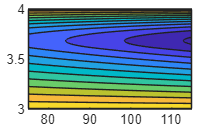

contourf(x_new,y,Z30)

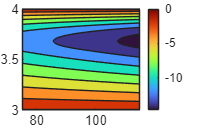

contourf(x_new,y,Z50)
colormap('turbo')
colorbar



% Plot
% xrange = 0:1:166;
% yrange = 0:0.1:4;
% [x,y] = meshgrid(xrange, yrange);
% figure


% plot(y,sigma_st)
% hold on
% xlabel('Height above center axis of bending, y')
% ylabel('Axial Stress in Stringer')
% title('\sigma_1 vs. y')
% grid on
% hold off
% 
% plot(y,sigma_sk)
% hold on
% xlabel('Height above center axis of bending, y')
% ylabel('Axial Stress in Skin')
% title('\sigma_1 vs. y')
% grid on
% hold off

#### Safety Check of Stringer

% Check yield
Y_st = 1e7; %psi FAKE VALUE
SF = 1.2;

counter = 0;
good_set = [];

for k= 1:d
    max_sigma_st = max(max(abs(sigma_st(:,:,k))));
    max_SF_sigma= max_sigma_st*SF;

    if max_SF_sigma < Y_st %no failure
        counter = counter + 1;
        good_set(end+1) = k;
    end 
end

#### Safety Check of Skin

% % Check yield
% 
% counter2 = 0;
% good_set2 = [];
% 
% for k= 1:d
%     max_sigma_sk = max(max(abs(sigma_st(:,:,k))));
%     max_SF_sigma_sk= max_sigma_sk*SF;
% 
%     if max_SF_sigma_sk < Y_sk %no failure
%         counter2 = counter2 + 1;
%         good_set2(end+1) = k;
%     end 
% end